# Seminar 7 - Kalman filter

**Authors:** Ing. David Vošahlík, prof. Ing. Vladimír Havlena, CSc.

## Introduction

Kalman filtering - well known and widely used technique - will be studied in this seminar. Kalman filter variants are all based on two main steps. The data update step and time update step. These can be used as needed e.g. your sampling time is much faster then your measurements, so you will make multiple time updates while having only one data update step.

## Joint covariance matrix update

Elementary important skill will be trained in this section. Let's assume that you are given a state covariance matrix *P. *Compute the covariance matrix of the next time step assuming you have the LTI model


$$x\left(t+1\right)=\mathrm{A}\;x\left(t\right)+\mathrm{B}\;u\left(t\right)+v\left(t\right)$$


$y\left(t\right)=\mathrm{C}\;x\left(t\right)+\mathrm{D}\;u\left(t\right)+e\left(t\right)$ ,

where the covariances are Q and R for the *v *and *e *respectively.

*Hint: *Use the error dynamics that is $\tilde{x} \left(t+1\right)=\mathrm{A}\;\tilde{x} \left(t\right)+v\left(t\right)$, where the $\tilde{x} \left(t\right)=x\left(t\right)-\hat{x} \left(t\right)$.


$$\begin{array}{l}
P\left(t+1\right)=\textrm{cov}\left(x\left(t+1\right)\right)=E\left\lbrace \tilde{x} \left(t+1\right)\cdot \tilde{x} {\left(t+1\right)}^T \right\rbrace =\\
E\left\lbrace \mathrm{A}\;\tilde{x} \left(t\right){\left(\mathrm{A}\;\tilde{x} \left(t\right)\right)}^T +\mathrm{A}\;\tilde{x} \left(t\right){v\left(t\right)}^T +v\left(t\right){\left(\mathrm{A}\;\tilde{x} \left(t\right)\right)}^T +v\left(t\right){v\left(t\right)}^T \right\rbrace =\\
E\left\lbrace \mathrm{A}\;\tilde{x} \left(t\right)\tilde{x} {\left(t\right)}^T \;{\mathrm{A}}^{\mathrm{T}} +v\left(t\right){v\left(t\right)}^T \right\rbrace =\mathrm{A}\;P\left(t\right)\;{\mathrm{A}}^{\mathrm{T}} +\mathrm{Q}\;
\end{array}$$


## Lead vehicle velocity estimation - Kalaman filtering

Try to look back into the third seminar where this example with more strict assumptions was used. The example introduction will be made again here with modest modification.

Imagine ego vehicle has information only about the position of the ahead of it going lead vehicle (LV). The ACC (adaptive cruise control) needs also LV's velocity for proper functionality. Assume that the unknown LV velocity is constant. So the LV model is rather simple:

$\begin{array}{l}
x\left(k+1\right)=\mathrm{A}\;x\left(k\right)+v\\
y\left(k\right)\;\;\;\;\;\;\;\;=\mathrm{C}\;x\left(k\right)+e
\end{array}$,

where $x=\left\lbrack \begin{array}{c}
v\\
s
\end{array}\right\rbrack$,$\;v\;\left\lbrack \frac{m}{s}\right\rbrack$ is LV velocity,  $s\;\left\lbrack m\right\rbrack$ is it's distance, $T_s \;\left\lbrack s\right\rbrack$ is sampling time, $e\left(t\right)$ is measurement noise with covariance R, $v\left(t\right)$ is process white noise with covariance Q. The matrices are:

$\mathrm{A}=\left\lbrack \begin{array}{cc}
1 & 0\\
T_s  & 1
\end{array}\right\rbrack$, $\mathrm{C}=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack$, Q = $\left\lbrack \begin{array}{cc}
1\cdot {10}^{-3}  & 0\\
0 & 1
\end{array}\right\rbrack$, R = 4

 Also the measurements are availible only once per 5 samples. Your task will be to:

- implement such model

- make sample measurements

- Implement the Kalman filter algorithm.

- Plot the estimates

- Plot also the 95% confidence interval of the velocity estimate. 

*Hint:* Start the estimation with *P*(1)* = *100*E (E is identity matrix)*.*

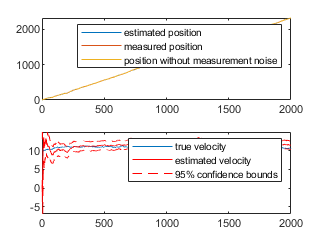

%% OFD: Seminar Week 7
% MATLAB excercises
% 
% David Vošahlík 2020

%% Bayesian formula (LV constant velocity estimation)

close all

% Number of measurements
n = 2000;
% Real LV velocity
LV_velo = 10;       % m/s
Ts = 0.1;           % s


% Covariance matrices
Q = [1e-3 0;
    0 1;];
R = 4;

% State space matrices
A = [1 0;
    Ts 1;];
C = [0 1];


% Generate random samples 
v = chol(Q)'*randn(size(Q,1),n); 
e = sqrt(R).*randn(1,n);

% initate the variables
x = zeros(2,n);
y = zeros(1,n);
sigv = zeros(1,n);
x_hat = zeros(2,n);
x(:,1) = [10; 0;];
P = cell(1, n);
P{1} = 100*eye(2);

% Plot estimates at samples
plot_values = [1:5,10:10:50,100:100:500,1000:1000:10000, 20000];
% plot_values = 1:n;
for i = 1:n
    % simulate the system
    x(:, i + 1) = A*x(:,i) + v(:,i);
    y(i) = C*x(:,i) + e(i);
    
    curP = P{i};                    % Currently used covariance matrix
    % Data update step every fifth sample
%     if mod(i, 5) == 0
        K = curP*C'/(C*curP*C'+R);  % Kalman gain
        x_hat(:,i) = x_hat(:,i) + K*(y(i)-C*x_hat(:, i)); % x_hat(t|t)
        curP = curP - K*C*curP;     % P(t|t)
%     end
    
    % time step
    x_hat(:,i+1) = A*x_hat(:,i);    % position update x_hat(t+1|t)
    curP = A*curP*A' + Q;           % covariance update P(t+1|t)
    P{i + 1} = curP;
    sigv(i) = sqrt(curP(1,1));
    
    if any(plot_values==i) || i == n
        subplot(211);
        clf;
        subplot(211);
        plot(1:i, C*x_hat(:,1:i));
        hold on;
        plot(1:i, y(1:i));
        plot(1:i, C*x(:,1:i));
        legend('estimated position', 'measured position', 'position without measurement noise');
        subplot(212);
        plot(1:i, x(1,1:i));
        hold on;
        plot(1:i, x_hat(1,1:i), 'r');
        plot(1:i, x_hat(1,1:i) + sigv(1:i)*2, 'r--');
        plot(1:i, x_hat(1,1:i) - sigv(1:i)*2, 'r--');
        ylim([(min(x_hat(1,:)) - 3) (max(x(1,:)) + 3)]);
        legend('true velocity', 'estimated velocity', '95% confidence bounds');
        pause(0.5);
    end
end